% This script was used to get the solved piecewise function of a non-differential function
% and a 6th order function for the S curve of the end effector's X position over 3 seconds

clear

syms t time  a6 a5 a4 a3 a2 a1 a0

T = 3;

p = t^6 + a5*t^5 + a4*t^4 + a3*t^3 + a2*t^2 + a1*t + a0

$$p = t^{6}+a_{5}\,t^{5}+a_{4}\,t^{4}+a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

pd = diff(p,t)

$$pd = 6\,t^{5}+5\,a_{5}\,t^{4}+4\,a_{4}\,t^{3}+3\,a_{3}\,t^{2}+2\,a_{2}\,t+a_{1}$$

pdd = diff(diff(p,t))

$$pdd = 30\,t^{4}+20\,a_{5}\,t^{3}+12\,a_{4}\,t^{2}+6\,a_{3}\,t+2\,a_{2}$$

tA_time = 1;
tA_pos = 52.5;
tA_speed = 0;
tA_acc = 0;

tB_time = 2;
tB_pos = 82.5;
tB_speed = 0;
tB_acc = 0;

p0 = subs(p,t,tA_time) == tA_pos;
p1 = subs(pd,t,tA_time) == tA_speed;
p2 = subs(pdd,t,tA_time) == tA_acc;

p3 = subs(p,t,tB_time) == tB_pos;
p4 = subs(pd,t,tB_time) == tB_speed;
p5 = subs(pdd,t,tB_time) == tB_acc;

S = solve([p0 p1 p2 p3 p4 p5],[a5 a4 a3 a2 a1 a0])

S = struct with fields:
    a5: [1×1 sym]
    a4: [1×1 sym]
    a3: [1×1 sym]
    a2: [1×1 sym]
    a1: [1×1 sym]
    a0: [1×1 sym]


A0 = S.a0, A1 = S.a1, A2 = S.a2, A3 = S.a3, A4 = S.a4, A5 = S.a5

$$A0 = -\frac{1739}{2}$$

$$A1 = 3564$$

$$A2 = -5334$$

$$A3 = 3837$$

$$A4 = -1317$$

$$A5 = 171$$

time = tA_time:0.01:tB_time;

P = time.^6 + A5*time.^5 + A4*time.^4 + A3*time.^3 + A2*time.^2 + A1*time + A0

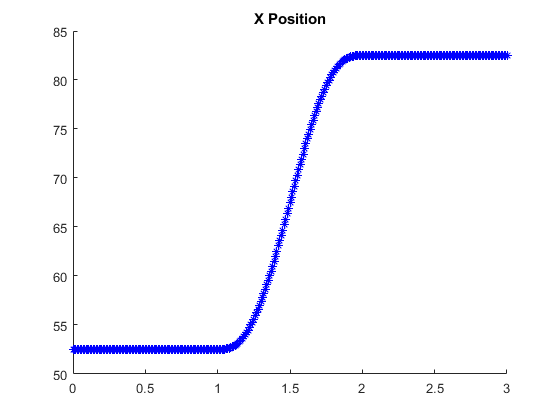

hold on
% Note that the x position will slightly increase before it is
% completely above the obstacles, but not enough for a collision
plot(0:0.01:tA_time, 52.5, 'b*');
plot(time, P, 'b*');
plot(tB_time:0.01:T, 82.5, 'b*');
title('X Position')
hold off;
hold on